# Tentsim BAS simulation code

Part I of this code will use a Gaussian-Lorentzian beam model to simulate a series of burst distribution timestreams based on various experimental parameters. The simulated data is stored in a format consistent with raw microscope data files gererated in the past (Header + Ascii columns) .

Will incorporate multi-channel (color) output later

Part II contains all function calls

Dependancies:

'gausswin' requires Signal Processing Toolbox.

NOTE: 

% Best to use the Export to PDF button up top to save output. 
% Use of matlab.internal.liveeditor.openAndConvert  is unstable and not
% supported by matlab

disp('Click Clear all Output button under VIEW tab in top bar of this window ')

Click Clear all Output button under VIEW tab in top bar of this window 


clear all  
% clc

% UPDATE when code is revised
versionnum= 'v1p9p2';

# Part I

    NA = 1; % Effective numerical aperture
    lam1 = 5.6e-7; % wavelength (m)
    lam2 = 6e-7; % wavelength (m)
    zRscale = 3; % unitless factor to elongate z
    % to simulate elongation of GL beam. This is a guess right now and not
    % optimized. Getting this number wrong means the effective concentration
    % will be off.
    % Set  scanning  and sampling time of instrument
    scanrate = 0.0005; % optical scan rate m/s {500um/s}
    sampletime = 0.0005; % time bin size (seconds) {500us/sample}

## Set excitation beam and dataset parameters

average concentration, resulting number of data points, sampling, scan speed, etc

Allow for two color channel  (16 Sep 2020)

%BAS beam parameters
% Using Abbe limit: w0 = lambda/(2 NA) ~lambda/2.9

w0_1 =  lam1/(2*NA);
w0_2 =  lam2/(2*NA);

% A few geometrical excitation volume estimators for reference (not
% critical)
zR1= zRscale*(pi*w0_1^2/lam1);  % scaled Raleigh range
zR2= zRscale*(pi*w0_2^2/lam2);  % scaled Raleigh range
V_GL1=(pi^2*w0_1^2*zR1/4);   %unsaturated volume for GL beam - not used
V_GL2=(pi^2*w0_2^2*zR2/4);   %unsaturated volume for GL beam - not used
A_GL1=2*w0_1*zR1;  %approx cros-sectional area in m^2; this underestimates actual 
% detected events by a significant factor when sensitivity extends down to
% 0.01*max as is assumed
A_GL2=2*w0_2*zR2;


% Set experimental conditions for time and particle concentration
filetime=60;% total data file time in seconds  (per single file)
particlecon=3e-10;% average total ensemble Molar concentration; change filename

% Base file name with path (no quotes; no .txt) used below when saving
% files
filebase="Sim_300pM_560600";

partperm3=particlecon*1000*6.023e23; %particles per m^3 based on concentration
effpartspacing=(1/partperm3)^(1/3);  % est. spacing between particles in meters
%based on concentration


%Physical width/length of one sample in meters
samplewidth = scanrate*sampletime;  %meteres/sample
numbersamples=filetime/sampletime; %samples
totalwidth=samplewidth*numbersamples; %total scan length in meters

% Estimate of sample volume in one sample
effvolsample1=A_GL1*scanrate*sampletime; % est. rectangular volume m^3 of one 
% sample during scan in x direction; this may not be same size as effective
% beam volume
effvolsample2=A_GL2*scanrate*sampletime;


approxpartpersamp1= effvolsample1*partperm3 ; %estimate of fraction # 
% particles per sample (not per beam volume); keep in mind detection limit
% is beyond effective beam volume by quite a bit so more particle stikes
% detected than this number (accounted for later by scaling)
approxpartpersamp2= effvolsample2*partperm3 ; 

% Use the avg fraction of particles per sample and total time to estimate
% the number of bursts to simulate within one effective GL beam volume; this
% will be scaled up based on user settings later. The scaling of number
% goes as the square of the wavelength ratio for Gaussian approximation
neventsamples1=round(filetime/sampletime * approxpartpersamp1); % estimated # detected in time
neventsamples2=round(filetime/sampletime * approxpartpersamp2);


out1=['Simulating ',num2str(neventsamples1),' significant bursts within primary volume'];
disp(out1)

Simulating 4005 significant bursts within primary volume


out1=['in ',num2str(filetime/sampletime),' sample bins...'];
disp(out1)

in 120000 sample bins...



out2=['Simulating ',num2str(neventsamples2),' significant bursts within primary volume'];
disp(out2)

Simulating 4598 significant bursts within primary volume


out2=['in ',num2str(filetime/sampletime),' sample bins...'];
disp(out2)

in 120000 sample bins...



% Check that there is no where near as many events as bins (single particle
% limit as needed for BAS). Choosing 10x as cutoff
if (filetime/sampletime < 10*neventsamples1) || (filetime/sampletime < 10*neventsamples2)
    disp(['Too concentrated to preserve single partical requirement. Adjust coding '])
    return
end

%Use button only to rerun this section
 

## Generate beam crossing amplitudes  & set number of sim files


% Display GL Beam Profile Model and generate beam crossing amplitudes for
% the given experiment parameters
% These represent crossing amplitude of all events but we will subdivide these into different particle
% distributions
% Each file constrained have the same number of bursts so not truly sampling noise
% with repeats

% Select number of runs (same sample run again) and repeats (fresh sample) for writing data files

runfiles=7;  %max of 20 run files is hardwired 
repeatfiles=1;  %max of 20 repeats files is hardwired 

totfiles = runfiles*repeatfiles; %
disp('Number of run of same sample: '),runfiles   

Number of run of same sample: 


runfiles = 7

disp('Number of repeats with fresh sample: '),repeatfiles   

Number of repeats with fresh sample: 


repeatfiles = 1

disp('Number of sim files generated: '),totfiles

Number of sim files generated: 


totfiles = 7



seedstate="shuffle" %shuffle initialize to clock state; default to seed=0

seedstate = "shuffle"

% effpartspacing is est. spacing between particles in meters
%based on concentration; totalwidth is length of entire scan 

%Factor by which to expand sampling volume ; same for both channels
% Set these so that model beam amplitude histogram fits powerlaw down to
% a value of 1/Dynrange
zfactor=3.5;%z-axis axial sample half range (m)
yfactor=2.5;%y-axis laterial sample half range (m)

Dynrange =200;%Usable dynamic range of intensity measurement
%determine number of sample points for scaled volume  Color A
scaledvol1=(2*zR1*zfactor)*(2*w0_1*yfactor)*totalwidth;  %scaled total scan volume to sample in m^3
nsamples1=round(scaledvol1/(effpartspacing^3));   %Est. of number of samples needed in rectangular 
% scaledvol; this should be over-estimate by at least zfactor*yfactor
% compared to number needed as set by estimate above. This will serve as a
% library of possible events to draw from.
disp(strcat("Number of event samples in one run of specified volume of simulated data: ",num2str(nsamples1)))

Number of event samples in one run of specified volume of simulated data: 70094



%determine number of sample points for scaled volume Color B
scaledvol2=(2*zR2*zfactor)*(2*w0_2*yfactor)*totalwidth;  %scaled total scan volume to sample in m^3
nsamples2=round(scaledvol2/(effpartspacing^3));   %Est. of number of samples needed in scaledvol
disp(strcat("Number of event samples in one run of specified volume of simulated data: ",num2str(nsamples2)))

Number of event samples in one run of specified volume of simulated data: 80465



%%% Whichever channel requires more sampling, use that to set number of
%%% points to sample. Excess sampling in more narrow beam will be
%%% <0.005*max value and discarded later.
if (neventsamples1 >= neventsamples2)
    nsamples =nsamples1;  %number for oversampling
    neventsamples=neventsamples1;  % number actually needed to sample to match concentration
    w0=w0_1;
    zR=zR1;
else
    nsamples=nsamples2;
    neventsamples=neventsamples2;
    w0=w0_2;
    zR=zR2;
end
% Sanity check that there is enough beam sampling about to happen to fill the
% estimated needed number of events neventsamples found above.
if (min([neventsamples1,neventsamples2]) > nsamples)
    disp(['Not enough data generated in random beam sampling for' ...
        'this choice of time & sampling. Adjust coding. '])
    return
end

    
%Sample same regions of space for both channels then discard events below
%set Dynmaic range threshold (typical 0.005*max)
%set state of random number generator (not needed)
s=rng(seedstate)

s = struct with fields:
     Type: 'twister'
     Seed: 454012168
    State: [625×1 uint32]


  Name          Size              Bytes  Class     Attributes

  B         80465x7             4506040  double              



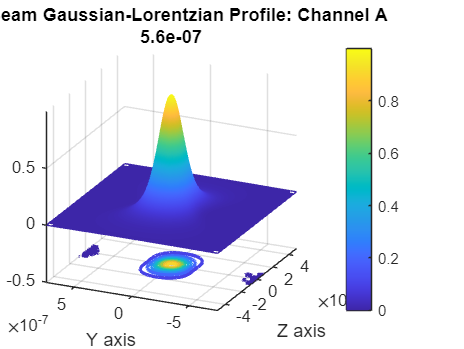

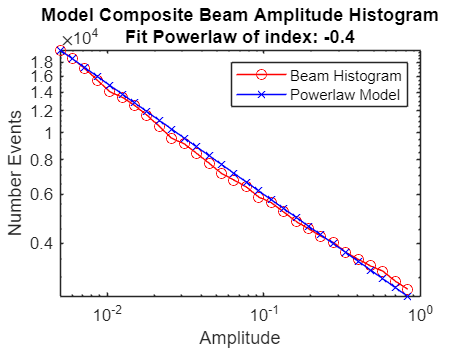

h = 1

  Name          Size              Bytes  Class     Attributes

  B         80465x7             4506040  double              



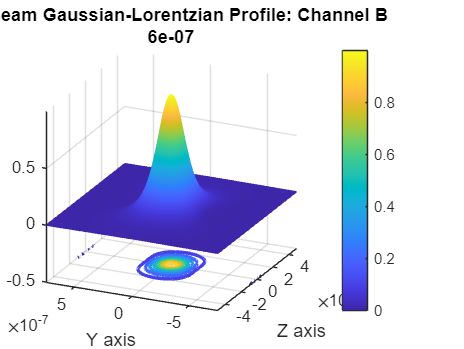

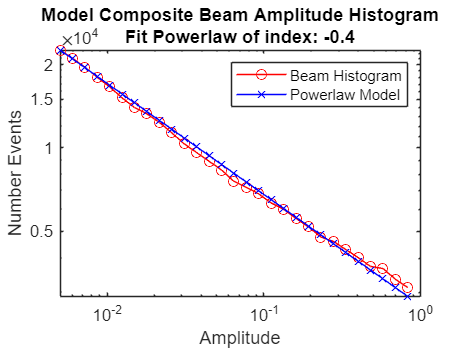

h = 1


%nsamples of (y,z) pairs with random placement in *rectangular* region set
% by larger beam
% Easier than sampling region based on GL shape. Shouldn't matter so long as
% enough sampling happens to generate values down to ~0.005 where beam shape model no
% longer valid
z=(-1+2*rand(nsamples,totfiles))*zfactor*zR;  %centered about value of 0
y=(-1+2*rand(nsamples,totfiles))*yfactor*w0;  %centered about value of 0


for chan=1:2

% Note: neventsamples is only meant as an estimate to correct number of detected
% bursts for a given concentration. Doesn't account for detector threshold
% set in analysis,etc. 

%%%%
if chan==1 
    w0=w0_1;
    zR=zR1;
    subtitle=num2str(lam1);
    plottitle='Y-Z Beam Gaussian-Lorentzian Profile: Channel A';
else
    w0=w0_2;
    zR=zR2;
    subtitle=num2str(lam2);
    plottitle='Y-Z Beam Gaussian-Lorentzian Profile: Channel B';
end

% Sample each beam model with spatial points determined above by larger beam
[BGL]= GLbeam(z, y, w0, zR, yfactor, zfactor); 
%[BG]= Gbeam(z, y, w0, zR, yfactor, zfactor); 

%Model experimental beam using a Gaussian-Lorentzian power law
%semi-empirical - seems to work though
BeamIndex =2.1; % Use 2.1 for BGL beam
BGL=BGL/max(BGL(:)); % Force Normalize to 1
B=BGL.^(BeamIndex);  

% Display composite beam shape
%Interpolate to show a surface plot of beam
znodes=-zfactor*zR:zR*.01:zfactor*zR;
ynodes=-yfactor*w0:w0*.01:yfactor*w0;
%grab 10000 random points to interpolate cause its faster
plotpnts=randi(length(B),10000,1);
[zgrid,xgrid,ygrid] = gridfit(y(plotpnts),z(plotpnts),B(plotpnts),ynodes',znodes');

%plot(y(plotpnts),z(plotpnts),B(plotpnts));

%Display cross-section
figure  %in case there was a lingering hold on
C=zgrid;
handles = meshc(ygrid,xgrid,zgrid,C);
view([-65.38 21.63]);
%title defined above per channel
ylabel('Y axis')
xlabel('Z axis')
title({plottitle,subtitle})
% handles is a 2-element array of handles: the surface plot and the contours
hContour = handles(2); % get the handle to the contour lines
hContour.ContourZLevel = -0.5; % set the contour's Z position (default: hAxes.ZLim(1)=-10)
% We can also customize other aspects of the contour lines, for example:
hContour.LineWidth = 2; % set the contour lines' width (default: 0.5)
hContour.LevelStep = .1;
colorbar

%Display histogram of resulting model beam shape
h=HistoBeam(B)  %Beam profile normalized to a max value of 1 at this point

% Each channel has beam model with same number of points sampled in same
% places in space but more narrow beam will have more amplitudes <0.005
% Shoud see that smaller amplitude events tend to have larger amplitudes in
% broader beam (e.g. red beam) if simple single species and same max amplitude
% used for both beams. 

% Now select first neventsamples of the nsamples amplitudes  in each beam;
% recall neventsamples is estimate of number of burst events for this
% concentration and beam size (see first part of code)
if chan==1 
    B1=B(1:neventsamples,:);
    z1=z(1:neventsamples,:);
    y1=y(1:neventsamples,:);
else
    B2=B(1:neventsamples,:);
    z2=z(1:neventsamples,:);
    y2=y(1:neventsamples,:);
end

end



%Use button only to rerun this section
 


## Generate starting amplitude distributions and fraction for each species

Select number of species ns (maximum of 3 for now) and amplitude distribution $A_i$ of each 

For each burst event, structure with time, original amp, beam crossing amp 

Set number of labels for each species to be used to determine color ratio between two channels

Simulated data is in counts so + integer values


distype= "flat"

distype = "flat"


switch (distype)
    case 'flat'
        disp('Fixed amplitude species')
%Amplitudes per label for each species/color channel
%Make as many samples as possible from 1000 to 2000, just A
        AmpS1ChA=3500;  
        AmpS1ChB=3500;  
        AmpS2ChA=0;  
        AmpS2ChB=0;  
        AmpS3ChA=0;  
        AmpS3ChB=0;  
        
%Species fractions
        Frac1=1;
        Frac2=    0;
        Frac3=    0;

% Number of fluors of each of two colors on a particle
        LabelNumS1ChA = 1
        LabelNumS1ChB = 1
        LabelNumS2ChA = 1
        LabelNumS2ChB = 1
        LabelNumS3ChA = 1
        LabelNumS3ChB = 1

        
        Frac1n=Frac1/(Frac1+Frac2+Frac3);
        Frac2n=Frac2/(Frac1+Frac2+Frac3);  % Effectively a normalized mix ratio
        Frac3n=Frac3/(Frac1+Frac2+Frac3);
    case '1/N'
        disp('To be added later')
           
end

Fixed amplitude species


LabelNumS1ChA = 1

LabelNumS1ChB = 1

LabelNumS2ChA = 1

LabelNumS2ChB = 1

LabelNumS3ChA = 1

LabelNumS3ChB = 1


% Generate same distribution for each wavelength channel but enforce color
% labeling factors
for chan=1:2

    if chan==1 
        B=B1;
    else
        B=B2;
    end
    
    nB=numel(B(:,1));
    p1=Frac1n*nB;
    p2=p1+Frac2n*nB;
    p3=p2+Frac3n*nB;
    
    Bdis=B*0; %initialize
    
    %scale by number of fluors per molecule
    if (Frac1n>0)
        if chan == 2
          Bdis(1:fix(p1),:)=AmpS1ChB*B(1:fix(p1),:)*LabelNumS1ChB; 
        else
          Bdis(1:fix(p1),:)=AmpS1ChA*B(1:fix(p1),:)*LabelNumS1ChA; 
        end   
    end
    if (Frac2n>0)
        if chan == 2
          Bdis(fix(p1)+1:fix(p2),:)=AmpS2ChB*B(fix(p1)+1:fix(p2),:)*LabelNumS2ChB; 
        else
          Bdis(fix(p1)+1:fix(p2),:)=AmpS2ChA*B(fix(p1)+1:fix(p2),:)*LabelNumS2ChA; 
        end
    end
    if (Frac3n>0)
        if chan == 2
          Bdis(fix(p2)+1:end,:)=AmpS3ChB*B(fix(p2)+1:end,:)*LabelNumS3ChB; 
        else
          Bdis(fix(p2)+1:end,:)=AmpS3ChA*B(fix(p2)+1:end,:)*LabelNumS3ChA; 
        end
        
    end
    
    if chan==1 
        Bdis1=Bdis;
    else
        Bdis2=Bdis;
    end

end

%Use button only to rerun this section
 

## Define time of events and amplitudes streams

assume random strike times and all events in channel with least number of strikes occur in other channel

>>> Working on defining time of events for channel A


Number of Channel A events contained in timestream:1945  1974  1897  1974  1875  1956  1995


Check histogram of scaled and dynamic range limited data stream before noise and convolved


edgemn = 0.9982

edgemx = 3.5000

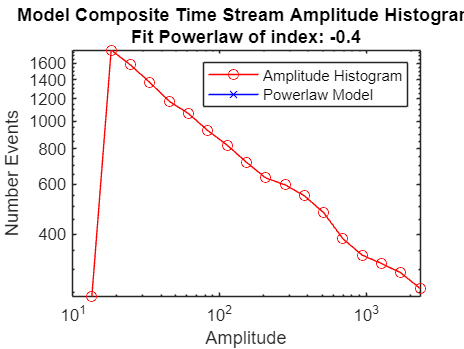

cummHeights
           0         242        1781        1578        1370        1176        1065         928         825         718         632         598         547         477         386         338         316         293         258



h = 1

>>> Working on defining time of events for channel B


Number of Channel B events contained in timestream:2251  2254  2174  2225  2168  2220  2278


Check histogram of scaled and dynamic range limited data stream before noise and convolved


edgemn = 0.9982

edgemx = 3.5000

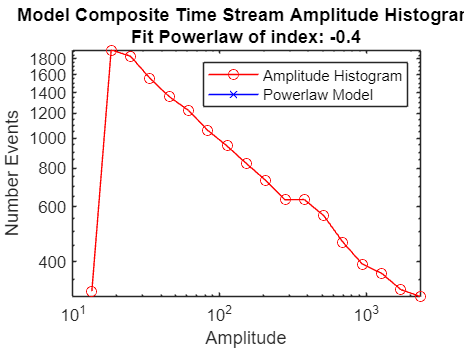

cummHeights
           0         321        1921        1836        1559        1361        1228        1059         943         828         731         633         634         563         462         393         367         325         309



h = 1

%Use same random event times for both channels. length(Bdis) should =  neventsamples
nsamplebins=round(filetime/sampletime);  %number of data points in single data file
bindex=randi(nsamplebins,neventsamples,totfiles);% select random indicies for burst events 
% in each of the datafiles to create (totfiles) 

for chan=1:2

    if chan==1 
        disp('>>> Working on defining time of events for channel A')
        Bdis=Bdis1;
        %use channel with least events to define
    else
        disp('>>> Working on defining time of events for channel B')
        Bdis=Bdis2;
    end
        
    ampstreams=zeros(nsamplebins,totfiles);  %initialize burst amplitude data
    for i=1:totfiles
        ampstreams(squeeze(bindex(:,i)),i)=Bdis(:,i);
    end

    
% Remove events whos amplitudes are less than 1/Dynrange
ampstreams(ampstreams < max([AmpS1ChA,AmpS1ChB,AmpS2ChA,AmpS2ChB,AmpS3ChA,AmpS3ChB])/Dynrange) = 0;

% Check new number of events
    if chan==1 
        neventsamp1=sum(ampstreams>0);
        disp(strcat('Number of Channel A events contained in timestream: ',num2str(neventsamp1)));
    else
        neventsamp2=sum(ampstreams>0);
        disp(strcat('Number of Channel B events contained in timestream: ',num2str(neventsamp2)));
    end
    
% Recheck histograms
disp('Check histogram of scaled and dynamic range limited data stream before noise and convolved')
h=HistoAmp(ampstreams)  %this is new for Sabreen's DL studies; previously,w/o logedge use in histobeam, range of 
%0 to 1 for ampstreams still 


%Use button only to rerun this section
 

## Convolve to simulate beam width and sampling (see Matlab gausswin)

The coefficients of a Gaussian window are computed from the following equation:

 
$$w(n)=e^{ -\frac{1}{2} \left( \frac{\alpha n}{(L-1)/2} \right)^2 = e^{-n^2 / (2\sigma ^2)}$$


where –(*L* – 1)/2 ≤ *n* ≤ (*L* – 1)/2, and *α* is inversely proportional to the standard deviation, *σ*, of a Gaussian random variable. The exact correspondence with the standard deviation of a Gaussian probability density function is *σ* = (*L* – 1)/(2*α*). In this case, $$\sigma=\frac{w0}{2}$$ so $\alpha=\frac{(L-1)}{2\sigma}=\frac{(L-1)}{w0}$

The 1/e2 width for the intensity profile is described by  $I(r)=I_{0}\exp \!\left(\!-2{\frac {r^{2}}{w^{2}}}\right)}$

    addspread =  true

addspread = logical
   1


addspread = logical
   1


Adding Gaussian spread to events...


L = 15

alphacorr = 2

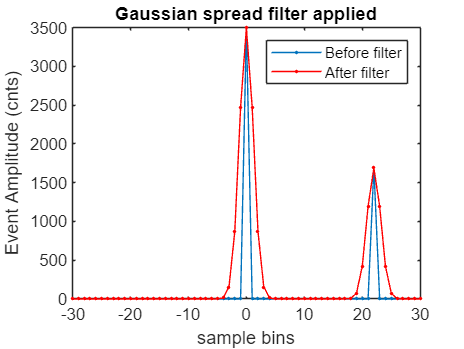

Adding Gaussian spread to events...


L = 15

alphacorr = 2

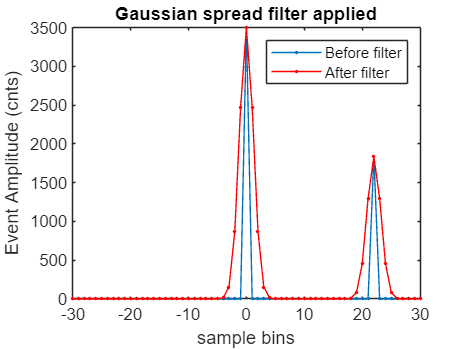

    
    if addspread
        
        disp('Adding Gaussian spread to events...')
    %Display effect
    qq=find(ampstreams == max(ampstreams(:)));  % Find index to the maximal event in all runs
    bigspikebefore=ampstreams(qq(1)-30:qq(1)+30);
        
        L=15 % Convolve window size L samples; 15 is reasonable 
    
    % For now, use same convolving filter for both channels. Use w0_2 which is the last defined w0 value 
    alpha=(L-1)/(w0/(scanrate*sampletime)); % standardly defined width factor
    
    alphacorr=2 %increase spread in time stream of 
    % a burst by correction factor (semi-empirical) ; default is 1.5
    
    gfilter=gausswin(L,alpha/alphacorr);
    
    %Convolve with filter that is normalized in amplitude to 1 so it leaves
    % event peaks with same amplitudes but adds Gaussian spread
    for i=1:totfiles
        ampstreams(:,i)=conv(ampstreams(:,i),gfilter,'same');
    end
    
    %Display effect (window of +/-30 for display purpose only)
    figure
    bigspikeafter=ampstreams(qq(1)-30:qq(1)+30);
    plot([-30:30],bigspikebefore,'.-')
    hold on
    plot([-30:30],bigspikeafter,'-r.')
    title({'Gaussian spread filter applied'})
    xlabel('sample bins')
    ylabel('Event Amplitude (cnts)')
    legend('Before filter','After filter','Location','northeast')
    hold off

    end


    if chan==1 
        ampstreamsA=ampstreams;
    else
        ampstreamsB=ampstreams;
    end
 
    
end

%Use button only to rerun this section
 

## Add noise (Not tested yet)

bkgrndnoise="None";
switch (bkgrndnoise)
    case 'Poisson'
        disp('Adding baseline Poisson noise ChA')
        lambdaA=15
        noiseamp=poissrnd(lambdaA,size(ampstreamsA,1),size(ampstreamsA,2));
        ampstreamsA=ampstreamsA+noiseamp;
        
        disp('Adding baseline Poisson noise ChB')
        lambdaB=15
        noiseamp=poissrnd(lambdaB,size(ampstreamsB,1),size(ampstreamsB,2));
        ampstreamsB=ampstreamsB+noiseamp;
        
    case 'Offset'
        disp('Add constant offset value ChA')          
        sigoffsetA=15
        ampstreamsA=ampstreamsA+sigoffsetA;  
        
        disp('Add constant offset value ChB')          
        sigoffsetB=15
        ampstreamsB=ampstreamsB+sigoffsetB;
        
    case 'Gaussian'
        disp('Adding baseline Gaussian noise ChA')
        meanA=10
        sigmaA=3
        noiseamp=normrnd(meanA,sigmaA,size(ampstreamsA,1),size(ampstreamsA,2));
        ampstreamsA=ampstreamsA+noiseamp;
        ampstreamsA(ampstreamsA<0)=0;
        
        disp('Adding baseline Gaussian noise ChB')
        meanB=10
        sigmaB= 3
        noiseamp=normrnd(meanB,sigmaB,size(ampstreamsB,1),size(ampstreamsB,2));
        ampstreamsB=ampstreamsB+noiseamp;
        ampstreamsB(ampstreamsB<0)=0;
        
end
signoiseA="None"; %same noise values added on each rerun of code 
switch (signoiseA)
    case 'Shot'
        disp('Adding shot noise ChA: var = mean count')
        for i=1:totfiles
            noiseamp=poissrnd(ampstreamsA(:,i));
            ampstreamsA(:,i)=squeeze(noiseamp);
        end
end
signoiseB="None"; %same noise values added on each rerun of code 
switch (signoiseB)
    case 'Shot'
        disp('Adding shot noise ChB: var = mean count')
        for i=1:totfiles
            noiseamp=poissrnd(ampstreamsB(:,i));
            ampstreamsB(:,i)=squeeze(noiseamp);
        end
end
            

%Use button only to rerun this section
 

## Apply species dynamics (TBD)

Select temporal profiles(flat, linear, exp) for each species

dynam="none";


## Check Inter-event interval to see if consistent with random event arrivals

checkisi =  true

checkisi = logical
   1


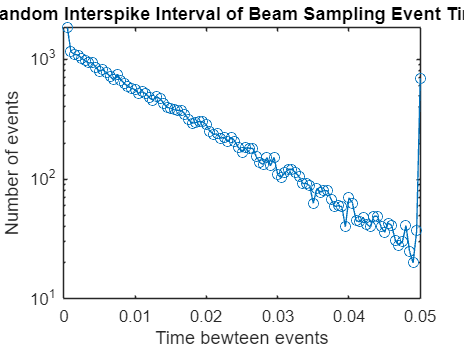

%This works in continuous limit but if sampling time is on the order of or
%larger than mean event time this will not work. In this case, need to set
%an amplitude threshold to limit number of events considered. Since the
%beam model is only valid to, say, 1% consider only events larger than 1%
%of the maximum amplitude.


if checkisi
    
%Check interspike interval using all events; first bin will be over loaded
%due to limit of bin size
striketimesm=randi([1,length(ampstreams(:))],length(bindex(:)),1);  
rtm=sort(striketimesm); %chronological order of event bins
peakshm=circshift(rtm,[1,0]);
peakdiffm=rtm - peakshm;  % This spacing (ISI) gives statistical measure of

%For reference, model of single population distribution with same avg event rate
% If multiple species, events should still be uncorrelated like 1 species
% of higher rate
nhistbins=100; %consider sampletime*nhistbins seconds of event spacing (typically 100ms)
xoutm=[1:nhistbins];
nm=hist(peakdiffm(2:end-1),xoutm);   %hist of random samples for control
semilogy(xoutm*sampletime,nm,'-o')
%subtitle=strcat("Random event model w/ single event rate: ",...
%    num2str(length(rtm)/(filetime*totfiles))," events/sec");
%title({'Random Interspike Interval of Beam Sampling Event Times';subtitle})
title('Random Interspike Interval of Beam Sampling Event Times')
xlabel('Time bewteen events')
ylabel('Number of events')

end



%Use button only to rerun this section
 

## Allow  time stream runs to be added  to simulate higher concentration (TBD)

Increasing concentration at start limited by  sample binning and uniform random distribution: doesn't yield correct high  concentration behavior. Allow co-adding  all run files

coadd =  false

coadd = logical
   0


%adds together all runfiles for a single repeat into one of same length
% Like adding signal prerounding to integer; binning still discrete and
% coadding doesn't account for this (very simple method)

if coadd && (runfiles > 1)
    nampstreams=zeros(length(ampstreams(:,1)),repeatfiles); %intialize new coadded 

    for j=1:repeatfiles
      tempamp=ampstreams(:,(j-1)*runfiles+1:j*runfiles);
      nampstreams(:,j)=sum(tempamp,2);
    end
    runfiles=1;
    ampstreams=nampstreams;
end


%Use button only to rerun this section
 


## Convert events to photon arrival times as alternate format

The amplitudes in ampstreams are binned average photon event rate in specified time bins (typically 500us)

To do this, cycle through the bins and assign random times in that bin based on the number of cnts in that bin. Use 

 28Aug2024  - JP

phottime =  false

if phottime



## Write simulated data to a series of files

Include header similar to this example:

`_____________________________________________________`

`3/30/2020  11:39 AM`

`Total aquisition time:  60.92 sec  `

`Bin width for correlator intensity data:  500.00 usec`

`Scan diamater: 0.40 mm`

`Scan speed:  0.50 mm/sec`

`Lasers Active:  488 @ 0.050 mW`

`Laser modulation not active`

`Notes: `

`1/400000 dilution of 40 nm GreenFS in miliQ water`

`***end header***`

`Corr_I_A        Corr_I_B`

*____________________________________________________________*

Data follows in 2 column integer text with tab separation:  *blue # coln    red # coln*

AmpFormatsavefiles =  false % PreTamu time binned raw file format 

savefiles = logical
   1


PhotTimesavefiles =  true % Newer Tamu photon arrival time raw file format 

if AmpFormatsavefiles
    
%Get information about this data run and create a director for this data store
[simfile, tstr]=Information(versionnum);
timestr=string(tstr);
newdir=strcat(simfile,'_',timestr)
mkdir(newdir)

%This report file will contain  plots from PREVIOUS run only so need to run
% this program twice  to use this option. Use the Export button up top to
% save report file instead!!!
reportfile=strcat('./',newdir,'/SimReport_prevrun.pdf');  

% Base file name with path (no quotes; no .txt) defined above with
% concentration

k=1;
tstr=datetime('now');
tstr.Format = 'ddMMMyy-HHmmss'
timestr=string(tstr);
%%%%%%%% Store a parameters file with all runfile names for use with Tentsim_Preprocess.mlx
filenameparam=strcat(timestr,'-','preparams.txt');
 filenameparam=strcat(newdir,'/',filenameparam); %stores params file in new directory
 fileIDparam = fopen(filenameparam,'w'); 
fprintf(fileIDparam,'%%%%    (maintain 5 header lines) \n');
fprintf(fileIDparam,'These data represent simulated data with 3 independent populations \n');
fprintf(fileIDparam,'These header lines can be used to explain the point of the data collection \n');
fprintf(fileIDparam,'and point to other informative files with additional information. \n');
fprintf(fileIDparam,'%%%% \n\n');

for i=1:repeatfiles
    for j=1:runfiles        
%%%%%%%% Write a data (w/o newdir prefix) file for each run into the preparam file
        filenamedat=strcat(timestr,'-',num2str(i),'-',num2str(j),'.txt');        
%%%%%%%% Add file name to preparam file
        fprintf(fileIDparam,filenamedat);
        fprintf(fileIDparam,'\n');

% Store data file into new dir for each run in a specific file in the new directory
        filename=strcat(newdir,'/',filenamedat);
        fileID = fopen(filename,'w');

%TAMU style header        
  fprintf(fileID, '%s\n\n', timestr);
  fprintf(fileID,'Total acquisition time:  1200 sec \n');  
  fprintf(fileID,'Bin width for correlator intensity data:  500.00 usec \n');
  fprintf(fileID,'Scan diamater: 0.40 mm \n');
  fprintf(fileID,'Scan speed:  0.50 mm/sec \n');
  fprintf(fileID,'Lasers Active:  488 @ 0.050 mW \n');
  fprintf(fileID,'Laser modulation not active \n');
  fprintf(fileID,'Notes: \n'); 
  fprintf(fileID,'Simulated data; See Report.pdf for additional parameters \n');
  fprintf(fileID,'***end header*** \n\n');
  fprintf(fileID,'I_A  I_B \n\n');
        %Load 
          outdat=[round(ampstreamsA(:,k)),round(ampstreamsB(:,k))];
        fprintf(fileID,'%i %i\r\n',outdat');
        fclose(fileID);
        k=k+1;
    end
end

fprintf(fileIDparam,'\n');
fprintf(fileIDparam,'headlines colA colB sampletime driftwinA driftwinB basethreshA basethreshB corrt dofit \n');
formatSpec='%i %i %i %2.2e %i %i %i %i %2.4f %i \n';
fprintf(fileIDparam,formatSpec,14, 1, 2, 500e-6, 0, 0, 1, 1, 0.003, 0); %defaults for baseline subtraction
fclose(fileIDparam);


end

tstr = datetime
   28Aug24-193011


version number:v1p9p2
Version information and details of modeling at bottom of mlx code below the Information function


newdir = "TentSim_v1p9p2_28Aug24-193011"

tstr = datetime
   28Aug24-193011





if PhotTimesavefiles
    
%Get information about this data run and create a director for this data store
[simfile, tstr]=Information(versionnum);
timestr=string(tstr);
newdir=strcat(simfile,'_',timestr)
mkdir(newdir)

%This report file will contain  plots from PREVIOUS run only so need to run
% this program twice  to use this option. Use the Export button up top to
% save report file instead!!!
reportfile=strcat('./',newdir,'/SimReport_prevrun.pdf');  

% Base file name with path (no quotes; no .txt) defined above with
% concentration

k=1;
tstr=datetime('now');
tstr.Format = 'ddMMMyy-HHmmss'
timestr=string(tstr);
%%%%%%%% Store a parameters file with all runfile names for use with Tentsim_Preprocess.mlx
filenameparam=strcat(timestr,'-','preparams.txt');
 filenameparam=strcat(newdir,'/',filenameparam); %stores params file in new directory
 fileIDparam = fopen(filenameparam,'w'); 
fprintf(fileIDparam,'%%%%    (maintain 5 header lines) \n');
fprintf(fileIDparam,'These data represent simulated data with 3 independent populations \n');
fprintf(fileIDparam,'These header lines can be used to explain the point of the data collection \n');
fprintf(fileIDparam,'and point to other informative files with additional information. \n');
fprintf(fileIDparam,'%%%% \n\n');

for i=1:repeatfiles
    for j=1:runfiles        
%%%%%%%% Write a data (w/o newdir prefix) file for each run into the preparam file
        filenamedat=strcat(timestr,'-',num2str(i),'-',num2str(j),'.txt');        
%%%%%%%% Add file name to preparam file
        fprintf(fileIDparam,filenamedat);
        fprintf(fileIDparam,'\n');

% Store data file into new dir for each run in a specific file in the new directory
        filename=strcat(newdir,'/',filenamedat);
        fileID = fopen(filename,'w');

%TAMU style header        
  fprintf(fileID, '%s\n\n', timestr);
  fprintf(fileID,'Total acquisition time:  ??? sec \n');  
  fprintf(fileID,'Clock 82.31 psec \n');
  fprintf(fileID,'Scan diamater: 0.40 mm \n');
  fprintf(fileID,'Scan speed:  0.50 mm/sec \n');
  fprintf(fileID,'Lasers Active:  488 @ 0.050 mW \n');
  fprintf(fileID,'Laser modulation not active \n');
  fprintf(fileID,'Notes: \n'); 
  fprintf(fileID,'Simulated data; See Report.pdf for additional parameters \n');
  fprintf(fileID,'***end header*** \n\n');

  %%%%%*****  *****  ****** Convert to time
  fprintf(fileID,'I_A  I_B \n\n');
        %Load 
          outdat=[round(ampstreamsA(:,k)),round(ampstreamsB(:,k))];
        fprintf(fileID,'%i %i\r\n',outdat');
        fclose(fileID);
        k=k+1;
    end
end

fprintf(fileIDparam,'\n');
fprintf(fileIDparam,'headlines colA colB sampletime driftwinA driftwinB basethreshA basethreshB corrt dofit \n');
formatSpec='%i %i %i %2.2e %i %i %i %i %2.4f %i \n';
fprintf(fileIDparam,formatSpec,14, 1, 2, 500e-6, 0, 0, 1, 1, 0.003, 0); %defaults for baseline subtraction
fclose(fileIDparam);


end
%Use button only to rerun this section
 


## Write a pdf report to subdirectory with new sim data (Unstable matlab behavior - save with Export button up top)

% % Need to run the whole .mlx code twice to have a correct  version saved.
% % Always seems to have previous run saved
% 
% import matlab.internal.liveeditor.LiveEditorUtilities
% 
% matlab.internal.liveeditor.openAndConvert(which(strcat(simfile,'.mlx')),char(reportfile));
% % outputdir=strcat('./',newdir)
% % options = struct('format','pdf','outputDir',outputdir)
% % publish(which(strcat(simfile,'.mlx')),options)

% Create a structure to hold the variables
global variables;
variables = struct();

% Set the variables in the structure
variables.versionnum = versionnum;
variables.tstr = tstr;
variables.filebase = filebase;
variables.NA = NA;
variables.lam1 = lam1;
variables.lam2 = lam2;
variables.zRscale = zRscale;
variables.scanrate = scanrate;
variables.sampletime = sampletime;



# Part II

## FUNCTIONS

## Sample Gaussian-Lorentzian beam shape and display

function [B]= GLbeam(z, y, w0, zR, yfactor, zfactor) %lam, effpartspacing, totalwidth, nruns, seedstate)

% Display graphic of beam shape and return random sampling of GL beam over
% specified 2D range specified.
% nsamples is number of bursts to simulate within one effective beam volume
% However, to reach lowest amplitude bursts need to expand cross-sectional
% size of sampling past effective beam edge and hence number of bursts
% increases. Giventypical particle spacing for concentration choice above
% (effpartspacing) the number of beam crossing locations is generated.

% zR= zRscale*(pi*w0^2/lam);  % Raleigh range (approximate edge of beam along z-axis; 
% w0 is edge along x or y direction

% 

% % % %Factor by which to expand sampling volume
% % % zfactor=15;%axial sample half range (m)
% % % yfactor=10;%laterial sample half range (m)
% % % LorentzFac = 1% Relative amount of Lorentzian shape
% % % 
% % % %determine number of sample points for scaled volume
% % % scaledvol=(2*zR*zfactor)*(2*w0*yfactor)*totalwidth;  %scaled volume to sample in m^3
% % % nsamples=round(scaledvol/(effpartspacing^3));   %Est. of number of samples needed in scaledvol
% % % disp(strcat("Number of event samples in one run of specified volume of simulated data: ",num2str(nsamples)))
% % % 
% % % % Note: nsamples is only meant as an estimate to correct number of detected
% % % % bursts for a given concentration. Doesn't account for detector threshold
% % % % set in analysis,etc. 
% % % 
% % % %set state of random number generator (not needed)
% % % s=rng(seedstate)
% % % 
% % % %nsamples of (y,z) pairs with random placement in *rectangular* region
% % % % Easier than sampling region based on GL shape. Should matter so long as
% % % % enough sampling happens to generate values <<0.01 where beam shape model no
% % % % longer valid
% % % z=(-1+2*rand(nsamples,nruns))*zfactor*zR;  %centered about value of 0
% % % y=(-1+2*rand(nsamples,nruns))*yfactor*w0;  %centered about value of 0

%Sample GL beam shape
wlor2=w0^2*(1+(z/zR).^2);  %Lorentzian component
B=(w0^2./wlor2).*exp(-2*((y.^2) ./wlor2));
whos B

%plot3(y(:),z(:),B(:),'.')

end


## Sample Gaussian beam shape and display

function [B]= Gbeam(z, y, w0, zR, yfactor, zfactor) %lam, effpartspacing, totalwidth, nruns, seedstate)

% Display graphic of beam shape and return random sampling of G beam over
% specified 2D range specified.
% nsamples is number of bursts to simulate within one effective beam volume
% However, to reach lowest amplitude bursts need to expand cross-sectional
% size of sampling past effective beam edge and hence number of bursts
% increases. Giventypical particle spacing for concentration choice above
% (effpartspacing) the number of beam crossing locations is generated.

% zR= zRscale*(pi*w0^2/lam);  % Raleigh range (approximate edge of beam along z-axis; 
% w0 is edge along x or y direction

% 

% % % %Factor by which to expand sampling volume
% % % zfactor=15;%axial sample half range (m)
% % % yfactor=10;%laterial sample half range (m)
% % % 
% % % %determine number of sample points for scaled volume
% % % scaledvol=(2*zR*zfactor)*(2*w0*yfactor)*totalwidth;  %scaled volume to sample in m^3
% % % nsamples=round(scaledvol/(effpartspacing^3));   %Est. of number of samples needed in scaledvol
% % % disp(strcat("Number of event samples in one run of specified volume of simulated data: ",num2str(nsamples)))
% % % 
% % % % Note: nsamples is only meant as an estimate to correct number of detected
% % % % bursts for a given concentration. Doesn't account for detector threshold
% % % % set in analysis,etc. 
% % % 
% % % %set state of random number generator (not needed)
% % % s=rng(seedstate)
% % % 
% % % %nsamples of (y,z) pairs with random placement in *rectangular* region
% % % % Easier than sampling region based on GL shape. Should matter so long as
% % % % enough sampling happens to generate values <<0.01 where beam shape model no
% % % % longer valid
% % % z=(-1+2*rand(nsamples,nruns))*zfactor*zR;  %centered about value of 0
% % % y=(-1+2*rand(nsamples,nruns))*yfactor*w0;  %centered about value of 0

%Sample Gaussian beam shape
B=exp(-2*((y.^2)/w0^2)).*exp(-2*((z.^2)/zR^2)) ;
whos B

%plot3(y(:),z(:),B(:),'.')

end


## Histogram of Beam Shape

function h=HistoBeam(B)
% Display histogram of beam shape
% Assume values of B normalized from 0 to 1.
% Bin data down to 0.5% with 30 bins
% Supperimpose a power law model of spectral index powern

figure
edgemn=(log10(0.005*max(B(:))));
edgemx=(log10(max(B(:))));
logedge = logspace(edgemn,edgemx,30);
[n,edges,xbins]=histcounts(B(:),logedge); 
loglog(logedge(1:end-1),n,'-ro')
hold on
%over plot a basic powerlaw model with index of powern as expected
powern =-0.4;

a=n(1);
b=(logedge(1)).^powern;
loglog(logedge(1:end-1),a/b*(logedge(1:end-1)).^powern,'-bx')
hold off
subtitle=strcat("Fit Powerlaw of index: ",num2str(powern));
title({'Model Composite Beam Amplitude Histogram';subtitle})
ylabel('Number Events')
xlabel('Amplitude')

legend('Beam Histogram','Powerlaw Model','Location','northeast')
h=1;

end

## Histogram of Time Stream Burst Amplitudes

function h=HistoAmp(B)
% Display histogram of time stream data amplitudes; just like HistoBeam
% except with logedge manually set to generate simulated cumm data for DL
% studies (24 Nov 2023)
% Values of B normalized by "Generate starting amplitude distributions and
% fraction for each species" section where species amplitude distributions
% set
% Bin data down to 0.5% with 30 bins
% Supperimpose a power law model of spectral index powern for reference
% ***Sabreen: Take out values, save in array for myself (column heights = cumm, set
% logedge to amp=2000 array)
% fix for zeroes at end- extend max even further to "catch" everything
% (make sure it is adjusted for number of bins, should extend past that)

Nlogedge = 20;  %dimension of cumm vectors / number of log bins between edgemn and edgemx

figure
edgemn=0.9982
assignin('base', 'edgemn', edgemn);  %assigns in matlab base workspace as well rather than pass it back in function?
% Increase from 3.2993 to 3.5
edgemx=3.5
assignin('base', 'edgemx', edgemx);
logedge = logspace(edgemn,edgemx,Nlogedge); %fixes logedge from 10 to 3162.3; last bin fron edgemx(N-1) to edgemx(N)

% Compute histogram
[n, ~, ~] = histcounts(B(:), logedge);
    
% Plot histogram
loglog(logedge(1:end-1), n, '-ro');  %used lowest edge of bin as bin intensity value to match dim of histogram
hold on
  
% Overplot a basic powerlaw model with index of powern as expected
powern = -0.4;
a = n(1);
b = (logedge(1)).^powern;
loglog(logedge(1:end-1), a/b*(logedge(1:end-1)).^powern, '-bx');
hold off
   
subtitle=strcat("Fit Powerlaw of index: ",num2str(powern));
title({'Model Composite Time Stream Amplitude Histogram';subtitle})
ylabel('Number Events')
xlabel('Amplitude')

legend('Amplitude Histogram','Powerlaw Model','Location','northeast')
h=1;
cummHeights = n;
disp('cummHeights');
disp(cummHeights);
assignin('base', 'cummHeights', cummHeights);

end

## Outputs code version information 

function [simfile, tstr]=Information(versionnum)
% Display version and hold introductory information


simfile=strcat('TentSim_',versionnum);

tstr=datetime('now');
tstr.Format = 'ddMMMyy-HHmmss'

disp(strcat('version number: ',versionnum))
%disp(strcat('Output file name: ',strcat(simfile,'-Report',string(tstr),'.pdf')))
disp(['Version information and details of modeling at bottom of mlx code ' ...
    'below the Information function'])
end


# Introduction

Particles will pass through an excitation beam where the amplitude of the detected fluorescnce burst will be sampled at some fixed rate. This coresponds to a spatial binning based on the scan speed. Typically, these parameters are dt=500e-6 seconds sampling bin and 500 um/sec scan rate. Raw data file headers will nominally contain this information. 

To simulate this burst amplitude data we construct a linear response model based on a Gaussian-Lorentzian profile:

**Modeling of Gaussian-Lorentzian beam for photon counting histogram simulation**

[https://www.google.com/url?sa=t&rct=j&q=&esrc=s&source=web&cd=8&ved=2ahUKEwiIq5HBqN3jAhUB2VkKHXnXD7YQFjAHegQIAhAB&url=http%3A%2F%2Fwww.cell.com%2Fbiophysj%2Fpdf%2FS0006-3495(05)72852-6.pdf&usg=AOvVaw0A3UGJxn7xw5EXHNRhFedG](https://www.google.com/url?sa=t&rct=j&q=&esrc=s&source=web&cd=8&ved=2ahUKEwiIq5HBqN3jAhUB2VkKHXnXD7YQFjAHegQIAhAB&url=http%3A%2F%2Fwww.cell.com%2Fbiophysj%2Fpdf%2FS0006-3495%2805%2972852-6.pdf&usg=AOvVaw0A3UGJxn7xw5EXHNRhFedG)

Biophysical Journal Volume 89 September 2005 2077–2090 2077Observation Volumes and g-Factors in Two-Photon Fluorescence Fluctuation SpectroscopyAttila Nagy, Jianrong Wu, and Keith M. Berland Physics Department, Emory University, Atlanta, Georgia 

The predicted burst amplitude follows the BAS reasoning laid out in the 2008 PNAS paper. To this end, we need to sample the 2D vertical cross-section of the GL shape subject to a threshold nominally ~1/100 of maximum (central) value. Specifically, the Lorenzian profile is along the z axis (optical axis) of the objective and is (in this model) circularly symmetric about this axis. All x-y plane cross-sections are Gaussian in shape. Transiting particles along x axis then sample uniformly a profile that is an y-z cross-section so that the intensity time profile is Gaussian in time (constant scan rate, no saturation, particle size assumed small compared to width of beam, etc.). The goal of this code is to generate simulated time data subject to various beam, rate and particle concentrastion parameters.

## Data collection and style

A series of data files are collected using the BAS instrument each of which represents either a rerun of the same sample or a repeat with a new ideally identically prepared sample. Each run is stored as a text data file with a header describing the sample and state of the instrument during that run. Typically, 1 to 10 runs are acquired and ~3 repeats occur.

In this simulation, up to 20 runs may be set. A repeat is inprinciple identical to a rerun so there is no need for a repeat index. When writing simulated data, there are several options offered for storing as runs and repeats.